# Демодуляция. Часть 2.

# Single Sideband Suppressed Carrier 

# (AM-SSB-SC)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Совместная передача сигналов с однополосной модуляцией

Как упоминалось ранее, главным преимуществом SSB модуляции является уменьшение ширины спектра модулированного сигнала в два раза по сравнению с обычной DSB модуляцией. Это означает, что в той же самой полосе можно одновременно передавать сообщения сразу от двух пользователей. Однако, при этом потребуется внести определенные изменения в думодулятор, чтобы на приемной стороне можно было разделить эти два сообщения.

Для наглядности пусть первый пользователь передает аудиосообщения и использует USB модуляцию. Второй пользователь передает сигнал, состоящий из трех гармонических тонов с помощью LSB модуляции. Оба сообщения переносятся на частоту несущей, равную 60 kHz, с помощью модулятора на основе преобразования Гильберта. 

В файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации 44.1 kHz. Частота несущей будет равна 60 kHz. Чтобы избежать наложения спектров, выберем итоговую частоту дискретизации модулированного сигнала в 5 раз больше частоты аудиосигнала, то есть 5 * 44.1 kHz. Это потребует провести интерполяцию для увеличения частоты дискретизации информационного сообщения.

Гармонические сигналы для второго пользователя также формируются на частоте дискретизации 44.1 kHz, а затем совместно с аудиосообщением переносятся на частоту несущей.

Скрипт, выполняющий формирование совместного модулированного сигнала, представлен ниже: 

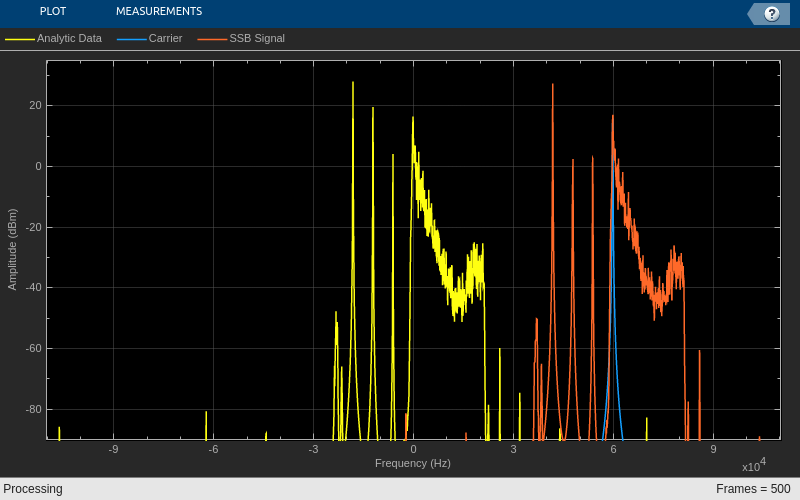

clc; clear; close all;

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 500;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации

% объект для считываения отсчетов аудиофайла
User1 = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = User1.SampleRate;                     % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% генератор тонального сигнала для второго пользователья 
User2 = dsp.SineWave(...
    'SampleRate', AudioFs,...
    'SamplesPerFrame', AudioFrameSize,...
    'Frequency', [6e3, 12e3, 18e3],...
    'Amplitude', [0.05, 0.3, 0.8]...
    );

% генератор несущей с частотой 60 kHz
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% объект вычисления преобразования Гильберта
% формирует аналитический сигнал
HilbertTranform1 = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

HilbertTranform2 = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Analytic Data', 'Carrier', 'SSB Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

SSBAmSignalArray = [];

% запуск симуляции
for i = 1:FramesNumber
    % формирование сигнала для первого пользователя
    User1Data = User1();
    User1Data = User1Data(:,1);
    
    % формирование сигнала для второго пользователя
    User2Data = User2();
    User2Data = User2Data(:,1) + User2Data(:,2) + User2Data(:,3);

    % формирование аналитических сигналов
    AnalyticUser1Data = HilbertTranform1(User1Data);
    AnalyticUser2Data = HilbertTranform2(User2Data);
    AnalyticUser2Data = conj(AnalyticUser2Data);

    % формирование совместного сигнала
    ComposedAnalyticData = AnalyticUser1Data + AnalyticUser2Data;
    
    % увеличение частоты дискретизации аудиосообщения
    UpsampledData = Upsampler(ComposedAnalyticData);
     
    % формирование несущей
    CarrierWave = Carrier(); 

    % перенос на частоте несущей
    SSBAmSignal = UpsampledData.*CarrierWave;
    SSBAmSignalArray = [SSBAmSignalArray SSBAmSignal];
    
    % вычисление спектров
    SpectrumData = SpecEstimator([UpsampledData, CarrierWave, SSBAmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На спектрограмме можно увидеть, что аудиосообщение от первого пользователя находится в верхней половине полосы модулированного сигнала. Три гармонических тона от второго пользователя располагаются в нижней половине спектра. Если в приемном устройстве просто умножить данный сигнал на несущую для переноса спектра на нулевую частоту, то это приведет к наложению спектров пользователей друг на друга. Поэтому демодулятор должен быть изменен, чтобы иметь возможность разделить сообщения пользователей. 

### 2. Демодулятор на основе низкочастотного фильтра

Один из вариантов разделения сообщений основан на методе, похожем на третий метод (third method) SSB модуляции. В дальнейшем будем считать, что выполняется квадратурный прием. Сигнал с помощью умножения на комплексную экспоненту переносится таким образом, чтобы нулевая частота совпала с серединой спектра одного из сообщений. Далее с помощью низкочастотного фильтра одно из сообщений удаляется, и полученный сигнал опять смещается, чтобы точно попасть на нулевую частоту. Для каждого из двух пользователей формируется своя ветвь со своим смешением по частоте.

Схема приемного устройства имеет вид:

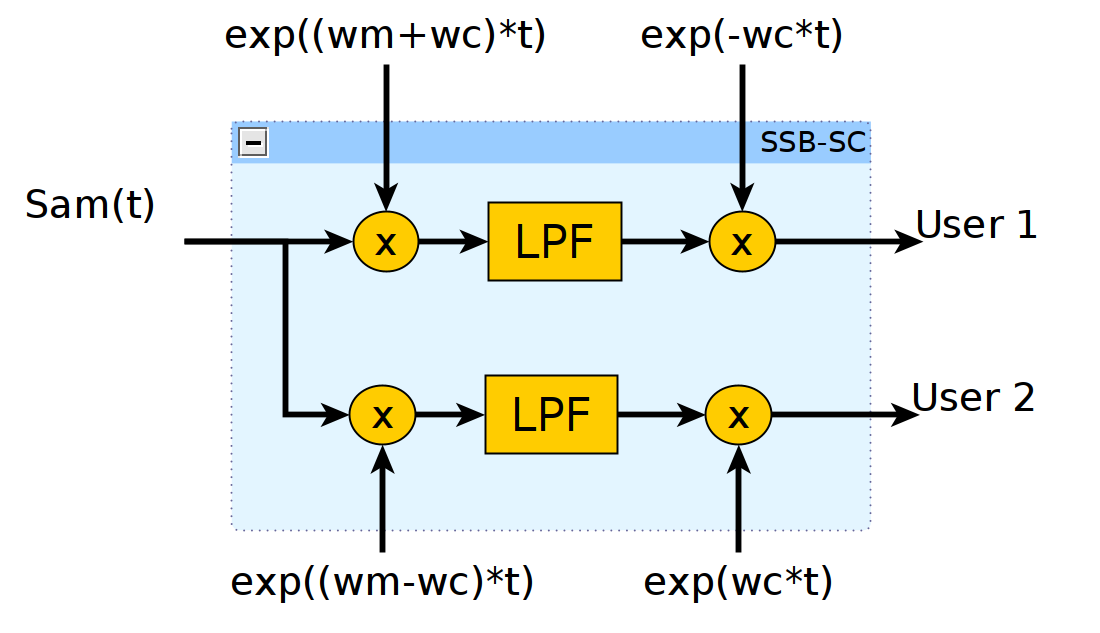

Ниже представлен скрипт, выполняющий описанные выше преобразования:

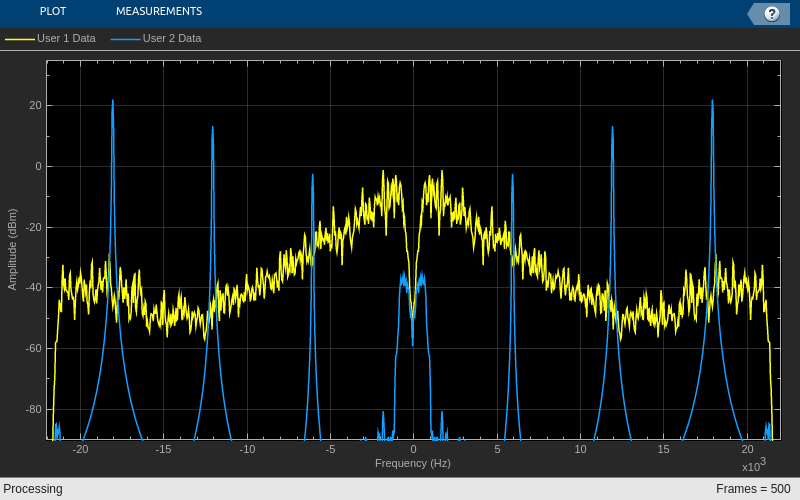

addpath('matlab/SSB_SC');

% генератор несущей для двух пользователей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', [60e3 + 11e3, 60e3 - 11e3],...
    'ComplexOutput', true, ...
    'Amplitude', [1, 1] ...
    );

% расчет коэффициентов и создание низкочастотного фильтра
H = Receiver_Baseband_FIR_Coeff(); 
BasebandFIR1 = dsp.FIRFilter(H.Numerator);
BasebandFIR2 = dsp.FIRFilter(H.Numerator);

% генераторы для переноса сигнала на нулевую частоту
BasebandMixer = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', [11e3 -11e3],...
    'ComplexOutput', true, ...
    'Amplitude', [1, 1] ...
    );

% дециматоры
DownSampler1 = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );
DownSampler2 = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',AudioFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -AudioFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'User 1 Data', 'User 2 Data'}, ...
    'SampleIncrement', AudioFs/AudioFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % получение отсчетов сигнала
    SSBAmSignal = SSBAmSignalArray(:,i);
    
    % получение несущей
    CarrierWave = Carrier();

    % смещение сигналов по частоте
    User1MixedData = SSBAmSignal .* conj(CarrierWave(:,1));
    User2MixedData = SSBAmSignal .* conj(CarrierWave(:,2));

    % низкочастотная фильтрация
    User1FilteredData = BasebandFIR1(User1MixedData);
    User2FilteredData = BasebandFIR2(User2MixedData);

    % получения комплексной экспоненты для компенсации сдвига по частоте
    BasebandWave = BasebandMixer();

    % компенсация сдвига по частоте
    User1BasebandData = User1FilteredData .* BasebandWave(:,1);
    User2BasebandData = User2FilteredData .* BasebandWave(:,2);

    % децимация
    User1Data = real(DownSampler1(User1BasebandData));
    User2Data = real(DownSampler2(User2BasebandData));

    Message = [Message; User1Data];

    % вычисление спектров
    SpectrumData = SpecEstimator([User1Data User2Data]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

На спектрограмме можно увидеть разделенные сообщения от первого (желтый) и второго (синий) пользователя . Из-за того, что низкочастотный фильтр имеет конечное ослабление в полосе подавления, низкочастотные спектранльные компоненты от первого пользователя попадают ко второму. Однако, они ослаблены до уровня -40 dB. В зависимости от решаемой задачи и технических требований этого может быть достаточно, а может быть и нет. Также можно увидеть, что из аудиосообщения удалены низкочастотные составляющие спектра.

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что удаления низкочастотных спектральных компенент из аудиосообщения на вносит существенных искажений.

### 3. Демодулятор на основе преобразования Гильберта

Другой способ разделения сообщений пользователей заключается в использовании преобразования Гильберта. В дальнейшем будем считать, что выполняется квадратурный прием. Принятый сигнал сразу переносится на нулевую частоту. Далее, используя преобразование Гильберта, можем виделить отдельно спектральные компоненты на положительных и отрицительных частотах. Это приводит к разделению сообщений от пользователей.

Схема приемного устройства имеет вид:

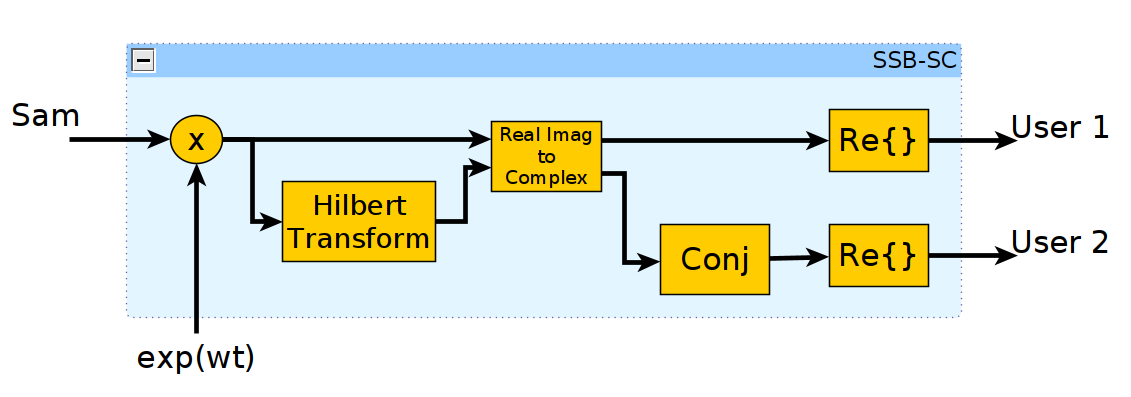

Ниже представлен скрипт, выполняющий описанные выше преобразования:

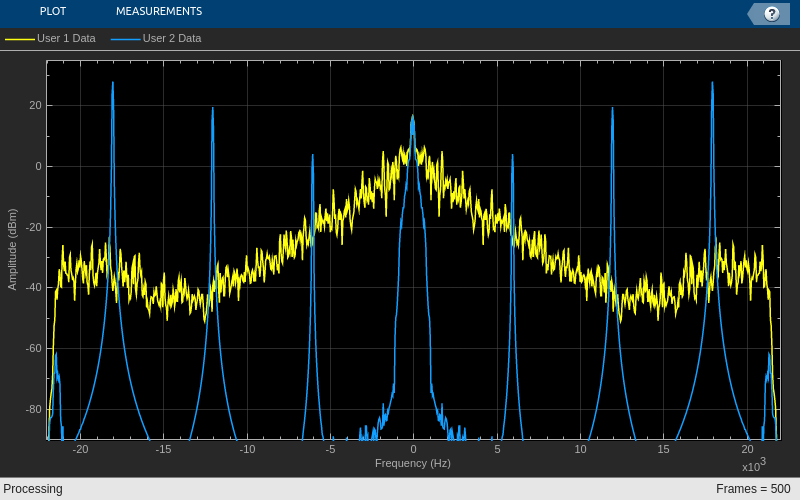

% генератор несущей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1 ...
    );

% дециматор
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект вычисления преобразования Гильберта
% формирует аналитический сигнал
HilbertTranform1 = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

HilbertTranform2 = dsp.AnalyticSignal(...
    'FilterOrder', 100 ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',AudioFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -AudioFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'User 1 Data', 'User 2 Data'}, ...
    'SampleIncrement', AudioFs/AudioFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % получение отсчетов сигнала
    SSBAmSignal = SSBAmSignalArray(:,i);
    
    % получение несущей
    CarrierWave = Carrier();

    % смещение сигнала по частоте
    BasebandSignal = SSBAmSignal .* conj(CarrierWave);

    % децимация
    DownSampledSignal = DownSampler(BasebandSignal);

    % разделение сигналов с помощью преобразования Гильберта
    % Matlab System Object dsp.AnalyticSignal требует на вход действительный 
    % сигнала, поэтому преобразование Гильберта вычисляется отдельно для
    % мнимой и действительной части. Так как эта операция линейная,
    % умножив преобразование от мнимой части на j и сложив с 
    % преобразованием от действительной части, получим 
    % односторонний спектр
    AnalyticDataReal = HilbertTranform1(real(DownSampledSignal));
    AnalyticDataImag = HilbertTranform2(imag(DownSampledSignal));
    AnalyticData = AnalyticDataReal + 1j.*AnalyticDataImag;

    % разделение сообщений
    User1Data = real(AnalyticDataReal + 1j.*AnalyticDataImag);
    User2Data = real(AnalyticDataReal - 1j.*AnalyticDataImag);

    Message = [Message; User1Data];

    % вычисление спектров
    SpectrumData = SpecEstimator([User1Data, User2Data]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

Обратите внимание, что в данном конкретном примере преобразования Гильберта не достаточно, чтобы удалить спектральные компоненты сообщения от первого пользователя. Данный подход хуже работает для сигналов, имеющий высокие спектральные составляющие в низкочастотной области, как в нашем аудиосообщении. Эти компонены попадают в сообщение второго пользователя. В Matlab преобразование Гильберта аппроксимируется с помощью КИХ-фильтра. Порядок этого фильтра, очевидно, слишком мал. 

Наоборот, сообщение второго пользователя состоит из трех гармонических тонов и не имеет низкочастотных компонент. Поэтому сообщение первого пользователя хорошо восстанавливается, что можно проверить на слух.

% проигрывание полученного сообщения
sound(Message, AudioFs);

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR